%% Klaydon Type X Polymer Bearing - Comprehensive Analysis
% Advanced Static and Dynamic Analysis for 3D Printed Bearings
% Dissertation Analysis Code
clear; clc; close all;

%% ==================== BEARING GEOMETRY PARAMETERS ====================
% *** MODIFY THESE PARAMETERS FOR DIFFERENT BEARING SIZES ***

% Klaydon Type X Bearing Dimensions (modify as needed)
bearing_params = struct();
bearing_params.inner_diameter = 8e-3;      % Inner raceway diameter [m]
bearing_params.outer_diameter = 22e-3;     % Outer raceway diameter [m]
bearing_params.width = 7e-3;               % Bearing width [m]
bearing_params.ball_diameter = 3.175e-3;   % Ball diameter [m] (1/8 inch standard)
bearing_params.n_balls = 8;                % Number of balls
bearing_params.pitch_diameter = 15e-3;     % Pitch circle diameter [m]
bearing_params.contact_angle = 0;          % Contact angle [degrees] (0 for radial)
bearing_params.inner_groove_radius = bearing_params.ball_diameter * 0.52; % Groove curvature
bearing_params.outer_groove_radius = bearing_params.ball_diameter * 0.52;

% Display bearing specifications
fprintf('=== KLAYDON TYPE X BEARING SPECIFICATIONS ===\n');

=== KLAYDON TYPE X BEARING SPECIFICATIONS ===


fprintf('Inner Diameter: %.1f mm\n', bearing_params.inner_diameter*1000);

Inner Diameter: 8.0 mm


fprintf('Outer Diameter: %.1f mm\n', bearing_params.outer_diameter*1000);

Outer Diameter: 22.0 mm


fprintf('Width: %.1f mm\n', bearing_params.width*1000);

Width: 7.0 mm


fprintf('Ball Diameter: %.3f mm\n', bearing_params.ball_diameter*1000);

Ball Diameter: 3.175 mm


fprintf('Number of Balls: %d\n', bearing_params.n_balls);

Number of Balls: 8


fprintf('Pitch Diameter: %.1f mm\n', bearing_params.pitch_diameter*1000);

Pitch Diameter: 15.0 mm


fprintf('==================================================\n\n');


%% ==================== MATERIAL PROPERTIES ====================
% Bambu Lab Filament Properties (from your data)
materials = {'PLA', 'PETG_HF', 'ABS', 'ASA', 'PC', 'PLA_CF', 'Nylon'};
material_display = {'PLA', 'PETG-HF', 'ABS', 'ASA', 'PC', 'PLA-CF', 'Nylon'}; % For display purposes

% Mechanical Properties
E = [2750, 2050, 1880, 1920, 2310, 3950, 1500] * 1e6;   % Bending Modulus [Pa]
sigma_y = [76, 64, 62, 65, 108, 89, 45] * 1e6;          % Bending Strength [Pa]
nu = [0.36, 0.38, 0.39, 0.38, 0.37, 0.35, 0.40];        % Poisson's Ratio
impact_xy = [26.6, 31.5, 39.3, 4.0, 34.6, 23.2, 35.0];  % Impact Strength [kJ/m²]

% Tribological Properties (estimated for polymer bearings)
mu_friction = [0.15, 0.18, 0.20, 0.17, 0.12, 0.10, 0.25];     % Friction coefficient
k_wear = [2e-7, 3e-7, 5e-7, 4e-7, 1e-7, 8e-8, 6e-7];          % Wear coefficient [mm³/Nm]
PV_limit = [0.3, 0.25, 0.2, 0.22, 0.35, 0.4, 0.15];           % PV limit [MPa·m/s]

% Steel ball properties
E_steel = 210e9;    % Steel modulus [Pa]
nu_steel = 0.3;     % Steel Poisson's ratio

%% ==================== STATIC ANALYSIS PARAMETERS ====================
% *** MODIFY THESE FOR YOUR COMPRESSION TESTING ***
static_loads = [50, 100, 200, 500, 1000]; % Test loads [N]
safety_factor_target = 2.0;               % Design safety factor

%% ==================== DYNAMIC ANALYSIS PARAMETERS ====================
% *** MODIFY THESE FOR YOUR DYNAMIC TESTING ***
dynamic_params = struct();
dynamic_params.radial_load = 100;         % Applied radial load [N]
dynamic_params.rpm_range = [100, 500, 1000, 2000]; % RPM test range
dynamic_params.test_duration = 3600;      % Test duration [seconds]
dynamic_params.total_cycles = 1e6;        % Target life cycles
dynamic_params.temperature_ambient = 25;   % Ambient temperature [°C]

%% ==================== PART 1: MATERIAL CHARACTERIZATION ====================
fprintf('=== MATERIAL CHARACTERIZATION ===\n');

=== MATERIAL CHARACTERIZATION ===



% Stress-Strain Curves
figure('Position', [100, 100, 1200, 800]);
subplot(2,2,1);
colors = lines(length(materials));
hold on;
for i = 1:length(materials)
    strain = linspace(0, 0.1, 100);
    stress = E(i) * strain .* (strain <= sigma_y(i)/E(i)) + ...
             sigma_y(i) * (strain > sigma_y(i)/E(i));
    plot(strain*100, stress/1e6, 'Color', colors(i,:), 'LineWidth', 2, ...
         'DisplayName', material_display{i});
end
xlabel('Strain (%)'); ylabel('Stress (MPa)');
title('Material Stress-Strain Curves');
legend('Location', 'southeast', 'FontSize', 8);
grid on; set(gca, 'FontSize', 10);

% Material Property Comparison
subplot(2,2,2);
[ax1, h1, h2] = plotyy(1:length(materials), E/1e9, 1:length(materials), sigma_y/1e6);
set(h1, 'LineStyle', '-', 'Marker', 'o', 'LineWidth', 2);
set(h2, 'LineStyle', '--', 'Marker', 's', 'LineWidth', 2);
set(ax1(1), 'XTick', 1:length(materials), 'XTickLabel', material_display);
set(ax1(2), 'XTick', 1:length(materials), 'XTickLabel', material_display);
ylabel(ax1(1), 'Modulus (GPa)'); ylabel(ax1(2), 'Strength (MPa)');
title('Material Properties Comparison');
legend('Modulus', 'Strength', 'Location', 'northwest');
grid on;

%% ==================== PART 2: STATIC HERTZIAN CONTACT ANALYSIS ====================
fprintf('=== STATIC HERTZIAN CONTACT ANALYSIS ===\n');

=== STATIC HERTZIAN CONTACT ANALYSIS ===



% Calculate contact stresses for each material and load
contact_results = struct();
R_ball = bearing_params.ball_diameter / 2;

for mat_idx = 1:length(materials)
    material_name = materials{mat_idx};
    contact_results.(material_name) = struct();
    
    % Effective modulus
    E_star = 1 / ((1-nu_steel^2)/E_steel + (1-nu(mat_idx)^2)/E(mat_idx));
    
    for load_idx = 1:length(static_loads)
        F = static_loads(load_idx);
        
        % Hertzian contact parameters
        a = ((3 * F * R_ball) / (4 * E_star))^(1/3); % Contact radius
        P_max = 3 * F / (2 * pi * a^2);              % Maximum pressure
        
        % Safety analysis
        safety_factor = sigma_y(mat_idx) / P_max;
        
        % Store results
        contact_results.(material_name).loads(load_idx) = F;
        contact_results.(material_name).contact_radius(load_idx) = a;
        contact_results.(material_name).max_pressure(load_idx) = P_max;
        contact_results.(material_name).safety_factor(load_idx) = safety_factor;
    end
    
    fprintf('%s Contact Analysis:\n', material_display{mat_idx});
    fprintf('  Max safe load (SF=%.1f): %.0f N\n', safety_factor_target, ...
            interp1(contact_results.(material_name).safety_factor, ...
                   contact_results.(material_name).loads, safety_factor_target));
    fprintf('  At 500N: σ_max = %.1f MPa, SF = %.2f\n', ...
            contact_results.(material_name).max_pressure(3)/1e6, ...
            contact_results.(material_name).safety_factor(3));
end

PLA Contact Analysis:


  Max safe load (SF=2.0): NaN N


  At 500N: σ_max = 530.4 MPa, SF = 0.14


PETG-HF Contact Analysis:


  Max safe load (SF=2.0): NaN N


  At 500N: σ_max = 442.0 MPa, SF = 0.14


ABS Contact Analysis:


  Max safe load (SF=2.0): NaN N


  At 500N: σ_max = 420.0 MPa, SF = 0.15


ASA Contact Analysis:


  Max safe load (SF=2.0): NaN N


  At 500N: σ_max = 423.3 MPa, SF = 0.15


PC Contact Analysis:


  Max safe load (SF=2.0): NaN N


  At 500N: σ_max = 475.5 MPa, SF = 0.23


PLA-CF Contact Analysis:


  Max safe load (SF=2.0): NaN N


  At 500N: σ_max = 669.0 MPa, SF = 0.13


Nylon Contact Analysis:


  Max safe load (SF=2.0): NaN N


  At 500N: σ_max = 364.0 MPa, SF = 0.12


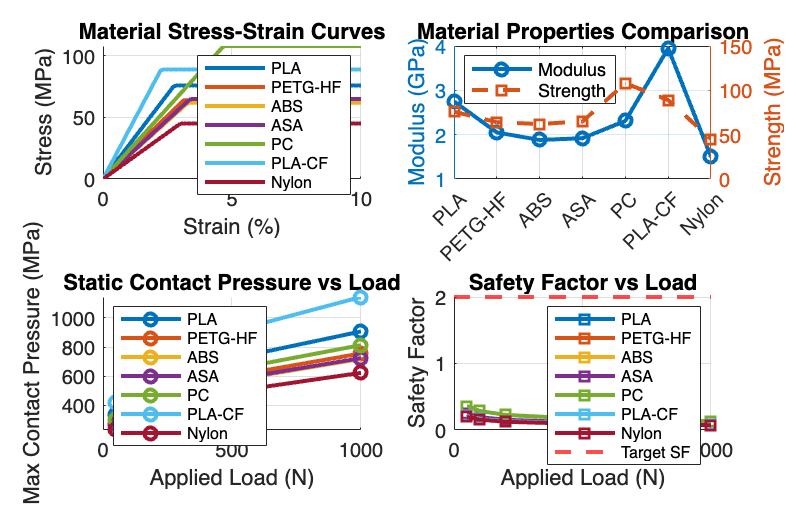


% Plot static analysis results
subplot(2,2,3);
hold on;
for i = 1:length(materials)
    plot(static_loads, contact_results.(materials{i}).max_pressure/1e6, ...
         'Color', colors(i,:), 'LineWidth', 2, 'Marker', 'o', ...
         'DisplayName', material_display{i});
end
xlabel('Applied Load (N)'); ylabel('Max Contact Pressure (MPa)');
title('Static Contact Pressure vs Load');
legend('Location', 'northwest', 'FontSize', 8);
grid on; set(gca, 'FontSize', 10);

% Safety factor plot
subplot(2,2,4);
hold on;
for i = 1:length(materials)
    semilogy(static_loads, contact_results.(materials{i}).safety_factor, ...
             'Color', colors(i,:), 'LineWidth', 2, 'Marker', 's', ...
             'DisplayName', material_display{i});
end
yline(safety_factor_target, 'r--', 'LineWidth', 2, 'DisplayName', 'Target SF');
xlabel('Applied Load (N)'); ylabel('Safety Factor');
title('Safety Factor vs Load');
legend('Location', 'northeast', 'FontSize', 8);
grid on; set(gca, 'FontSize', 10);


%% ==================== PART 3: DYNAMIC LOAD DISTRIBUTION ====================
fprintf('\n=== DYNAMIC LOAD DISTRIBUTION ANALYSIS ===\n');


=== DYNAMIC LOAD DISTRIBUTION ANALYSIS ===



% Ball positions and load distribution
theta = linspace(0, 2*pi, bearing_params.n_balls+1); 
theta(end) = []; % Remove duplicate point
load_angle = pi/2; % Radial load at top

% Load distribution (Stribeck's equation approximation)
load_factors = max(cos(theta - load_angle), 0).^1.5; % Nonlinear distribution
load_factors = load_factors / sum(load_factors);

% Dynamic analysis for each RPM
dynamic_results = struct();

for rpm_idx = 1:length(dynamic_params.rpm_range)
    rpm = dynamic_params.rpm_range(rpm_idx);
    
    % Calculate dynamic loads on each ball
    Q = dynamic_params.radial_load * load_factors; % Load per ball [N]
    
    % Centrifugal effects (simplified)
    omega = rpm * 2 * pi / 60; % Angular velocity [rad/s]
    centrifugal_load = 0.01 * omega^2 * bearing_params.pitch_diameter/2; % Approximate
    Q_total = Q + centrifugal_load;
    
    dynamic_results.(['rpm_' num2str(rpm)]) = struct();
    dynamic_results.(['rpm_' num2str(rpm)]).loads = Q_total;
    dynamic_results.(['rpm_' num2str(rpm)]).max_load = max(Q_total);
    dynamic_results.(['rpm_' num2str(rpm)]).omega = omega;
    
    fprintf('RPM %d: Max ball load = %.1f N (includes centrifugal)\n', ...
            rpm, max(Q_total));
end

RPM 100: Max ball load = 45.7 N (includes centrifugal)
RPM 500: Max ball load = 45.9 N (includes centrifugal)
RPM 1000: Max ball load = 46.5 N (includes centrifugal)
RPM 2000: Max ball load = 49.0 N (includes centrifugal)



%% ==================== PART 4: FATIGUE LIFE PREDICTION ====================
fprintf('\n=== FATIGUE LIFE PREDICTION ===\n');


=== FATIGUE LIFE PREDICTION ===



% Modified bearing life equation for polymers
L10_hours = zeros(length(materials), length(dynamic_params.rpm_range));

for mat_idx = 1:length(materials)
    for rpm_idx = 1:length(dynamic_params.rpm_range)
        rpm = dynamic_params.rpm_range(rpm_idx);
        max_load = dynamic_results.(['rpm_' num2str(rpm)]).max_load;
        
        % Dynamic capacity (empirical for polymers)
        C_dynamic = 0.2 * sigma_y(mat_idx) * bearing_params.ball_diameter^2;
        
        % Modified L10 life equation
        p_exponent = 3; % For ball bearings
        L10_revolutions = (C_dynamic / max_load)^p_exponent * 1e6;
        L10_hours(mat_idx, rpm_idx) = L10_revolutions / rpm / 60;
        
        % Adjust for PV limit
        v_sliding = rpm * pi * bearing_params.ball_diameter / 60; % m/s
        PV_actual = (max_load / bearing_params.ball_diameter^2) * v_sliding / 1e6; % MPa⋅m/s
        
        if PV_actual > PV_limit(mat_idx)
            L10_hours(mat_idx, rpm_idx) = L10_hours(mat_idx, rpm_idx) * ...
                                         (PV_limit(mat_idx) / PV_actual)^2;
        end
    end
    
    fprintf('%s Life Prediction:\n', material_display{mat_idx});
    fprintf('  500 RPM: %.0f hours, 1000 RPM: %.0f hours\n', ...
            L10_hours(mat_idx, 2), L10_hours(mat_idx, 3));
end

PLA Life Prediction:


  500 RPM: 780 hours, 1000 RPM: 91 hours


PETG-HF Life Prediction:


  500 RPM: 324 hours, 1000 RPM: 38 hours


ABS Life Prediction:


  500 RPM: 188 hours, 1000 RPM: 22 hours


ASA Life Prediction:


  500 RPM: 263 hours, 1000 RPM: 31 hours


PC Life Prediction:


  500 RPM: 3048 hours, 1000 RPM: 356 hours


PLA-CF Life Prediction:


  500 RPM: 1993 hours, 1000 RPM: 261 hours


Nylon Life Prediction:


  500 RPM: 41 hours, 1000 RPM: 5 hours



%% ==================== PART 5: WEAR AND TEMPERATURE ANALYSIS ====================
fprintf('\n=== WEAR AND TEMPERATURE ANALYSIS ===\n');


=== WEAR AND TEMPERATURE ANALYSIS ===



% Wear simulation
wear_results = struct();
operating_rpm = 500; % Reference RPM for wear analysis
rpm_idx = find(dynamic_params.rpm_range == operating_rpm);

for mat_idx = 1:length(materials)
    material_name = materials{mat_idx};
    
    % Operating parameters
    max_load = dynamic_results.(['rpm_' num2str(operating_rpm)]).max_load;
    sliding_velocity = operating_rpm * pi * bearing_params.ball_diameter / 60; % m/s
    
    % Wear calculation (Archard's equation)
    sliding_distance_per_hour = sliding_velocity * 3600; % m/h
    wear_rate = k_wear(mat_idx) * max_load / bearing_params.ball_diameter^2; % mm³/m
    wear_per_hour = wear_rate * sliding_distance_per_hour / 1000; % mm³/h
    
    % Temperature rise (simple friction model)
    power_friction = mu_friction(mat_idx) * max_load * sliding_velocity; % W
    mass_bearing = 0.01; % kg (estimate)
    cp_polymer = 1800; % J/kg⋅K
    temp_rise_steady = power_friction / (mass_bearing * cp_polymer * 0.1); % °C (with heat dissipation)
    
    wear_results.(material_name) = struct();
    wear_results.(material_name).wear_rate = wear_per_hour;
    wear_results.(material_name).temp_rise = temp_rise_steady;
    
    fprintf('%s at %d RPM:\n', material_display{mat_idx}, operating_rpm);
    fprintf('  Wear rate: %.2e mm³/h\n', wear_per_hour);
    fprintf('  Temperature rise: %.1f°C\n', temp_rise_steady);
end

PLA at 500 RPM:


  Wear rate: 2.72e-01 mm³/h


  Temperature rise: 0.3°C


PETG-HF at 500 RPM:


  Wear rate: 4.09e-01 mm³/h


  Temperature rise: 0.4°C


ABS at 500 RPM:


  Wear rate: 6.81e-01 mm³/h


  Temperature rise: 0.4°C


ASA at 500 RPM:


  Wear rate: 5.45e-01 mm³/h


  Temperature rise: 0.4°C


PC at 500 RPM:


  Wear rate: 1.36e-01 mm³/h


  Temperature rise: 0.3°C


PLA-CF at 500 RPM:


  Wear rate: 1.09e-01 mm³/h


  Temperature rise: 0.2°C


Nylon at 500 RPM:


  Wear rate: 8.17e-01 mm³/h


  Temperature rise: 0.5°C


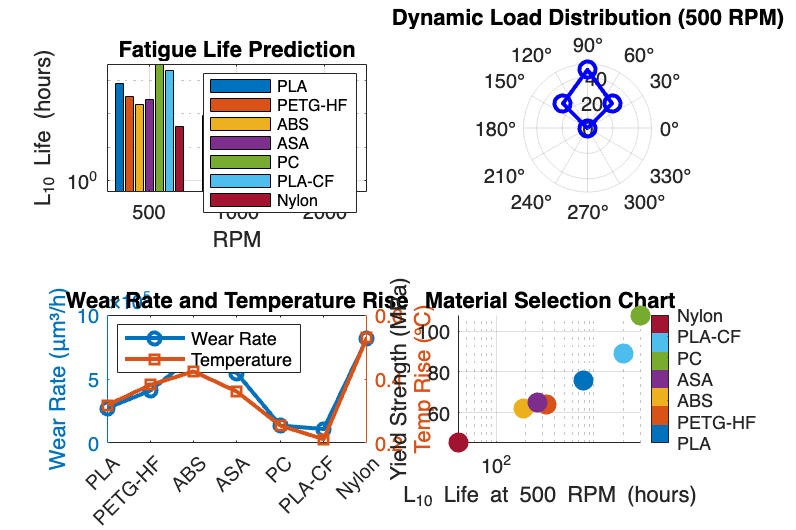


%% ==================== PART 6: VISUALIZATION AND RESULTS ====================

% Fatigue life comparison
figure('Position', [150, 150, 1200, 800]);
subplot(2,2,1);
bar_data = L10_hours(:, 2:4); % RPM 500, 1000, 2000
bar(bar_data');
set(gca, 'XTickLabel', {'500', '1000', '2000'});
xlabel('RPM'); ylabel('L_{10} Life (hours)');
title('Fatigue Life Prediction');
legend(material_display, 'Location', 'northeast', 'FontSize', 8);
grid on; set(gca, 'YScale', 'log');

% Dynamic load distribution visualization
subplot(2,2,2);
rpm_ref = 500;
Q_ref = dynamic_results.(['rpm_' num2str(rpm_ref)]).loads;
polarplot(theta, Q_ref, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
title(sprintf('Dynamic Load Distribution (%d RPM)', rpm_ref));
rlim([0 max(Q_ref)*1.1]);

% Wear comparison
subplot(2,2,3);
wear_rates = zeros(size(materials));
temp_rises = zeros(size(materials));
for i = 1:length(materials)
    wear_rates(i) = wear_results.(materials{i}).wear_rate;
    temp_rises(i) = wear_results.(materials{i}).temp_rise;
end
[ax1, h1, h2] = plotyy(1:length(materials), wear_rates*1e6, 1:length(materials), temp_rises);
set(h1, 'Marker', 'o', 'LineWidth', 2);
set(h2, 'Marker', 's', 'LineWidth', 2);
set(ax1(1), 'XTick', 1:length(materials), 'XTickLabel', material_display);
set(ax1(2), 'XTick', 1:length(materials), 'XTickLabel', material_display);
ylabel(ax1(1), 'Wear Rate (μm³/h)'); ylabel(ax1(2), 'Temp Rise (°C)');
title('Wear Rate and Temperature Rise');
legend('Wear Rate', 'Temperature', 'Location', 'northwest');

% Material selection chart
subplot(2,2,4);
life_index = L10_hours(:, 2); % 500 RPM life
strength_index = sigma_y / 1e6;
scatter(life_index, strength_index, 100, 1:length(materials), 'filled');
xlabel('L_{10} Life at 500 RPM (hours)'); ylabel('Yield Strength (MPa)');
title('Material Selection Chart');
colormap(lines(length(materials)));
cb = colorbar; cb.Ticks = 1:length(materials); cb.TickLabels = material_display;
grid on; set(gca, 'XScale', 'log');


%% ==================== PART 7: COMPARISON TABLES FOR DISSERTATION ====================
fprintf('\n=== SUMMARY TABLES FOR DISSERTATION ===\n');


=== SUMMARY TABLES FOR DISSERTATION ===



% Static performance table
fprintf('\nTable 1: Static Performance (500N Load)\n');


Table 1: Static Performance (500N Load)


fprintf('Material\tMax Pressure (MPa)\tSafety Factor\tContact Radius (μm)\n');

Material	Max Pressure (MPa)	Safety Factor	Contact Radius (μm)


fprintf('--------\t------------------\t-------------\t------------------\n');

--------	------------------	-------------	------------------


for i = 1:length(materials)
    fprintf('%s\t\t%.1f\t\t\t%.2f\t\t%.0f\n', material_display{i}, ...
            contact_results.(materials{i}).max_pressure(3)/1e6, ...
            contact_results.(materials{i}).safety_factor(3), ...
            contact_results.(materials{i}).contact_radius(3)*1e6);
end

PLA		530.4			0.14		424
PETG-HF		442.0			0.14		465
ABS		420.0			0.15		477
ASA		423.3			0.15		475
PC		475.5			0.23		448
PLA-CF		669.0			0.13		378
Nylon		364.0			0.12		512



% Dynamic performance table
fprintf('\nTable 2: Dynamic Performance (500 RPM)\n');


Table 2: Dynamic Performance (500 RPM)


fprintf('Material\tL10 Life (hours)\tWear Rate (μm³/h)\tTemp Rise (°C)\n');

Material	L10 Life (hours)	Wear Rate (μm³/h)	Temp Rise (°C)


fprintf('--------\t---------------\t------------------\t--------------\n');

--------	---------------	------------------	--------------


for i = 1:length(materials)
    fprintf('%s\t\t%.0f\t\t\t%.2f\t\t\t%.1f\n', material_display{i}, ...
            L10_hours(i, 2), wear_results.(materials{i}).wear_rate*1e6, ...
            wear_results.(materials{i}).temp_rise);
end

PLA		780			272408.77			0.3
PETG-HF		324			408613.15			0.4
ABS		188			681021.91			0.4
ASA		263			544817.53			0.4
PC		3048			136204.38			0.3
PLA-CF		1993			108963.51			0.2
Nylon		41			817226.30			0.5



% Export results to workspace for further analysis
assignin('base', 'bearing_params', bearing_params);
assignin('base', 'contact_results', contact_results);
assignin('base', 'dynamic_results', dynamic_results);
assignin('base', 'wear_results', wear_results);
assignin('base', 'L10_hours', L10_hours);


=== ANALYSIS COMPLETE ===


Results exported to workspace variables:


- bearing_params: Bearing geometry


- contact_results: Static contact analysis


- dynamic_results: Dynamic load distribution


- wear_results: Wear and temperature analysis


- L10_hours: Fatigue life predictions



Modify parameters at the top of the script for different configurations.
